**流域不对称性（AF, Asymmetry Factor）**

根据 Hack(1973)，AF 值能够用于判断流域是否经历过构造倾斜时间。盆地不对称因子是一种描述盆地内河流网络结构和形态的形态学分析方法。其计算公式为：


$$\textrm{AF}=100\cdot \left(\frac{A_r }{A_t }\right)$$


其中，$A_r$表示流域的右侧面积（以流域中主沟为分界），$A_t$表示流域的总面积。

构造影响对 AF 值变化敏感，AF 值在对称性流域中趋近 50 表示流域基本未受构造活动影响而处于相对稳定的状态；当流域盆地向左侧倾斜时(面向流向)，AF值正偏离50；相反，流域盆地向右倾斜时，其AF值会负偏离50。

AF值超过50或低于50分别与盆向左或向右倾斜有关（Keller和Pinter，2002）。对于最小岩性条件，AF值表示构造活动水平的差异（El Hamdouni等人，2008年;佩雷兹-佩纳等人，2010年）的报告。| AF-50型|用于量化流域的对称性。| AF − 50型|可分为三类：AF值>15、7-15和<7分别被分为高、中和低盆不对称性。

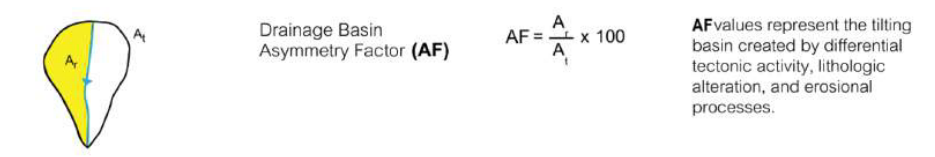

function AF_index = ttb_calculate_af_index(dem, main_stream, show)
    [main_stream_x, main_stream_y] = STREAMobj2XY(main_stream);
    basin = drainagebasins(FLOWobj(dem));
    [~, basin_x, basin_y] = GRIDobj2polygon(basin);

    % 计算总面积
    total_area = calculate_polygon_area(basin_x, basin_y);

    % 获取水流方向右侧子多边形的坐标序列
    if show
        figure;
        imageschs(dem);
        hold on;
        plot(main_stream_x, main_stream_y, 'Color', 'r', 'LineWidth', 2);
        plot(basin_x, basin_y, 'Color', 'k', 'LineWidth', 1);
        [side_sub_basin_x, side_sub_basin_y] = split_basin_by_main_stream(main_stream_x, main_stream_y, basin_x, basin_y);
        plot(side_sub_basin_x, side_sub_basin_y,  'Color', 'g', 'LineWidth', 2)
        hold off;
    else
        [side_sub_basin_x, side_sub_basin_y] = split_basin_by_main_stream(main_stream_x, main_stream_y, basin_x, basin_y);
    end

    % 计算主干流右侧的流域面积
    side_area = calculate_polygon_area(side_sub_basin_x, side_sub_basin_y);
    
    AF_index = 100 * side_area / total_area;
end

function area = calculate_polygon_area(polygon_x, polygon_y)
    % 使用叉积公式计算多边形面积
    x = polygon_x(:);
    y = polygon_y(:);

    cross = x(1:end-2) .* y(2:end-1) - x(2:end-1) .* y(1:end-2);
    cross = cross(~isnan(cross));

    area = 0.5 * abs(sum(cross));
end

function [right_basin_x, right_basin_y] = split_basin_by_main_stream(main_stream_x, main_stream_y, basin_x, basin_y)
    % 按照干流线串来分割流域多边形，收集其单边一侧的坐标序列
    
    % 计算河流的方向向量
    vec1 = [main_stream_x(2) - main_stream_x(1), ...
            main_stream_y(2) - main_stream_y(1)];
    vec2 = [main_stream_x(end-1) - main_stream_x(end-2), ...
            main_stream_y(end-1) - main_stream_y(end-2)];
    
    % 归一化方向向量
    vec1 = vec1 / norm(vec1);
    vec2 = vec2 / norm(vec2);
    
    % 确定延伸长度
    extend_length = 1e4; % 10,000 units, 根据实际范围调整
    
    % 延伸线段两端
    start_point = [main_stream_x(1), main_stream_y(1)] - extend_length * vec1;
    end_point = [main_stream_x(end-1), main_stream_y(end-1)] + extend_length * vec2;
    
    % 找到延伸到流域边界的交点
    [intersect1_x, intersect1_y, idx1] = polyxpoly([main_stream_x(1), start_point(1)], ...
                                              [main_stream_y(1), start_point(2)], ...
                                              basin_x, basin_y);
    [intersect2_x, intersect2_y, idx2] = polyxpoly([main_stream_x(end-1), end_point(1)], ...
                                              [main_stream_y(end-1), end_point(2)], ...
                                              basin_x, basin_y);

    % 将河流拼接为与流域多边形接壤的切割线串
    main_stream_x = flipud([intersect1_x; main_stream_x(1:end-1); intersect2_x]);
    main_stream_y = flipud([intersect1_y; main_stream_y(1:end-1); intersect2_y]);

    p1 = idx1(2);
    p2 = idx1(2) + 1;
    p3 = idx2(2);
    p4 = idx2(2) + 1;
    
    % 按照序号拼接从源头点到出水口点方向的右边的子流域
    if p1 > p4
        right_basin_x = [basin_x(1:p3); main_stream_x; basin_x(p2:end); basin_x(1)];
        right_basin_y = [basin_y(1:p3); main_stream_y; basin_y(p2:end); basin_y(1)];
    else
        right_basin_x = [basin_x(p2:p3); main_stream_x; basin_x(p2)];
        right_basin_y = [basin_y(p2:p3); main_stream_y; basin_y(p2)];
    end
end